addpath '/MATLAB Drive/Predictive Modeling and Machine Learning/Code Files/Evaluation Functions';

taxiData = loadAndProcessTaxiData("Taxi Data");

entireTaxiData = vertcat(taxiData{:});

initialExploratoryDataAnalysis;

entireTaxiDataCleaned = basicPreprocessing(entireTaxiData);
clear entireTaxiData taxiData;

postCleaningExploratoryDataAnalysis;

clear currentVars endIdx f j nPlots numFigures startIdx varsPerFigure;

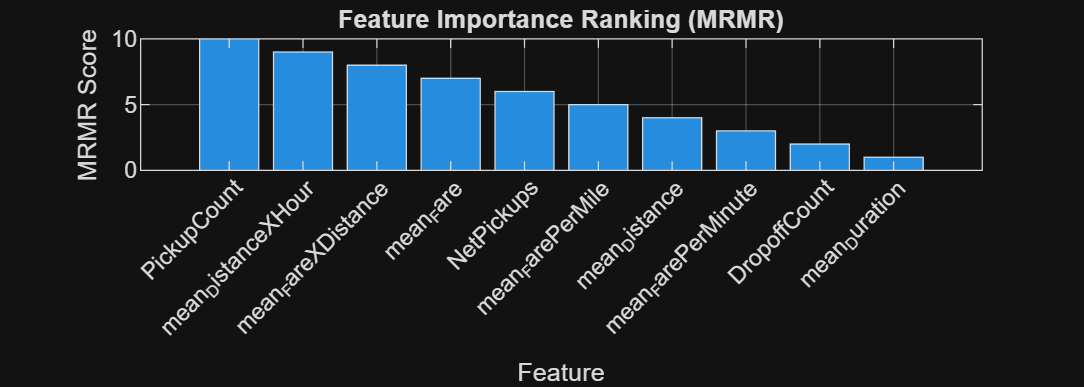

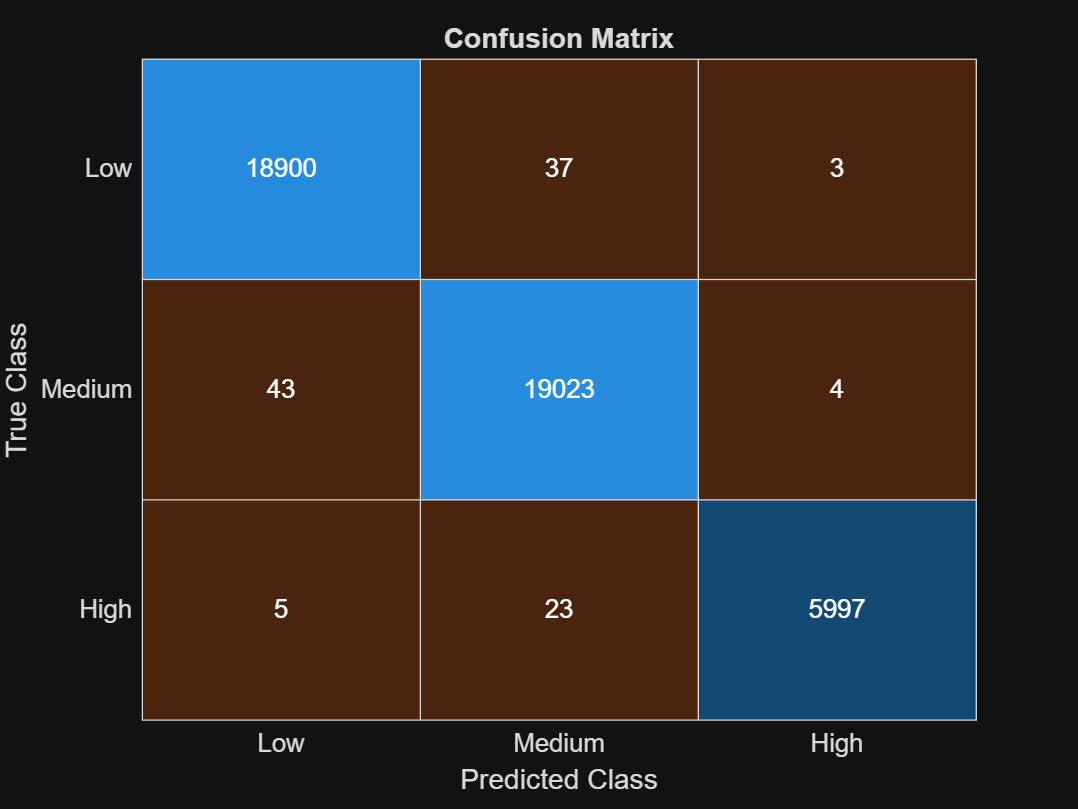

resultsS1 = struct with fields:
             Accuracy: 0.9974
             PerClass: [3×11 table]
       MacroPrecision: 0.9977
          MacroRecall: 0.9969
     MacroSpecificity: 0.9985
              MacroF1: 0.9973
             MacroFPR: 0.0015
             MacroFDR: 0.0023
    WeightedPrecision: 0.9974
       WeightedRecall: 0.9974
           WeightedF1: 0.9974
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]


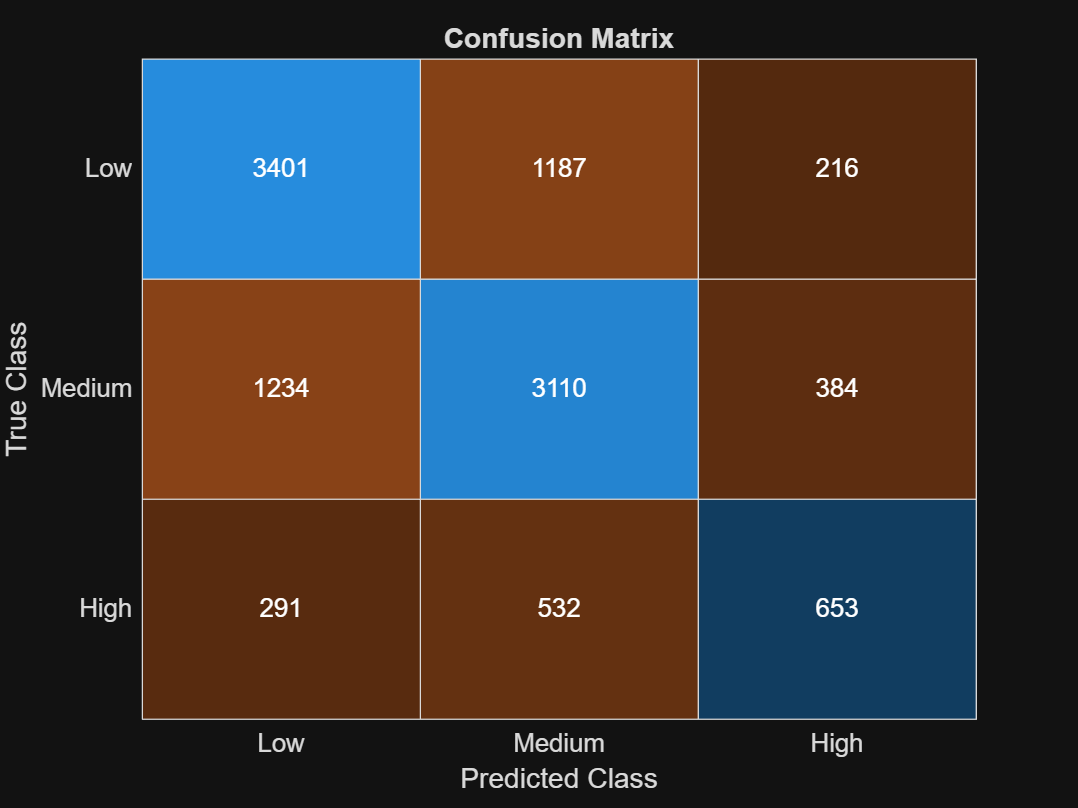

resultsS1Tested = struct with fields:
             Accuracy: 0.6508
             PerClass: [3×11 table]
       MacroPrecision: 0.6185
          MacroRecall: 0.6027
     MacroSpecificity: 0.8058
              MacroF1: 0.6095
             MacroFPR: 0.1942
             MacroFDR: 0.3815
    WeightedPrecision: 0.6478
       WeightedRecall: 0.6508
           WeightedF1: 0.6488
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]


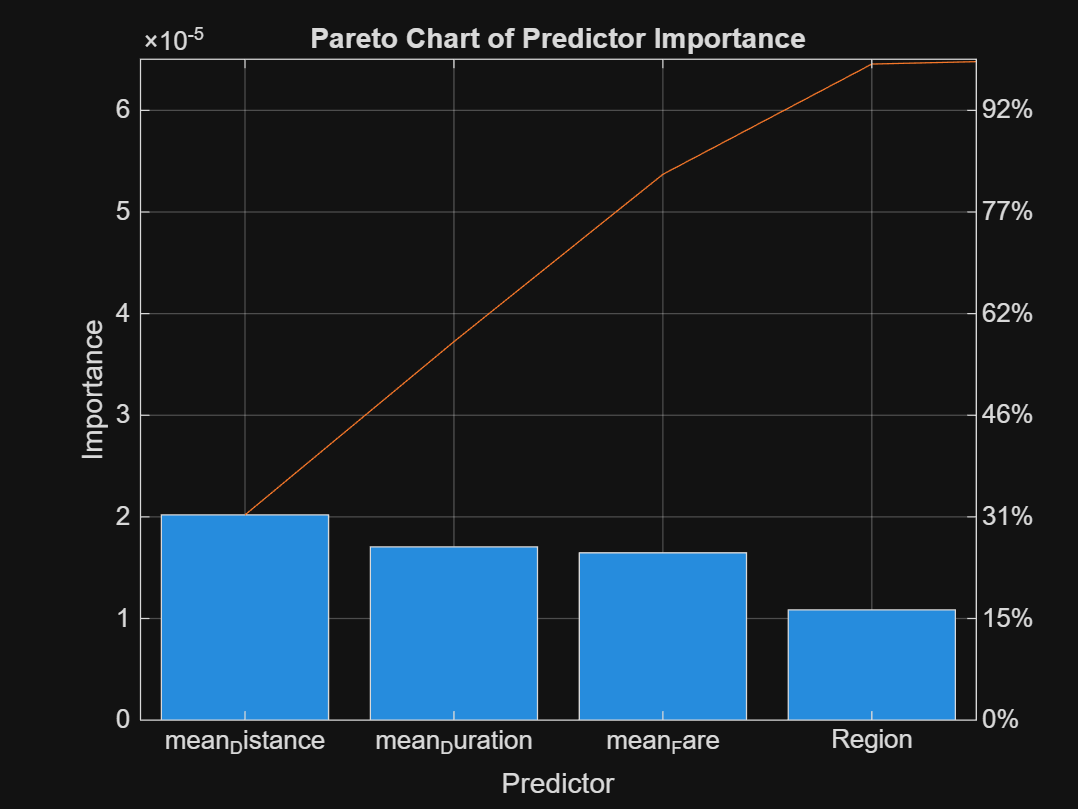

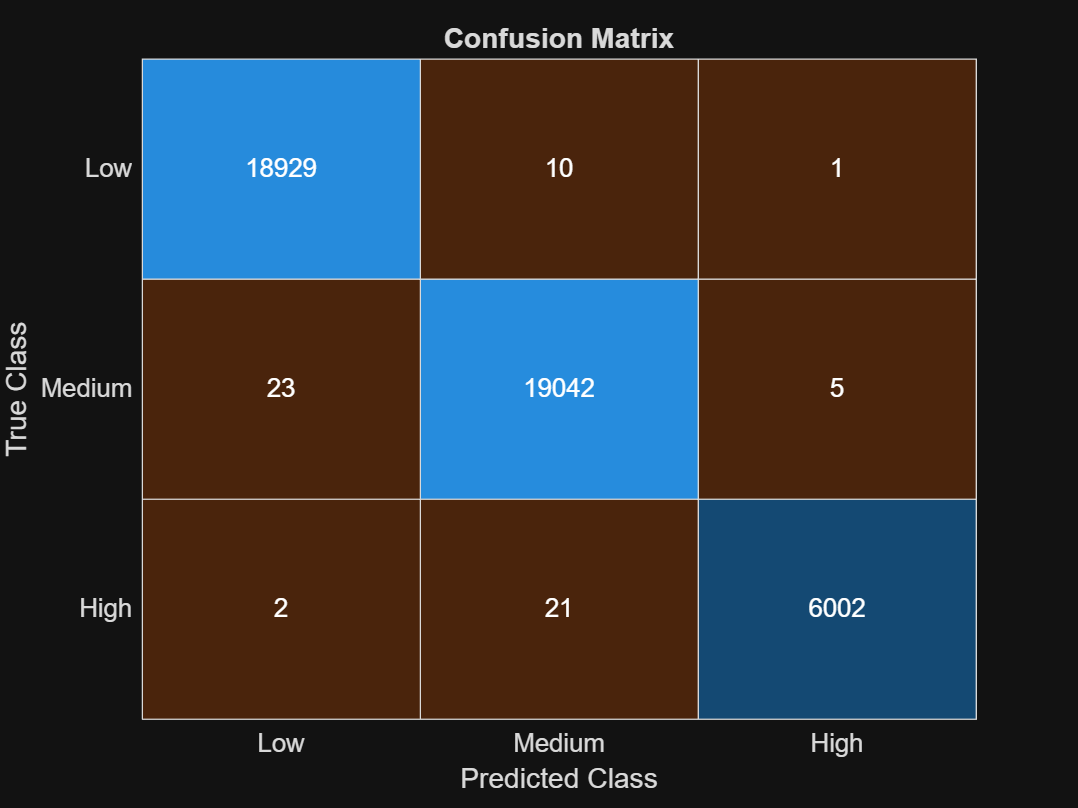

resultsS1_5 = struct with fields:
             Accuracy: 0.9986
             PerClass: [3×11 table]
       MacroPrecision: 0.9987
          MacroRecall: 0.9980
     MacroSpecificity: 0.9992
              MacroF1: 0.9984
             MacroFPR: 7.9860e-04
             MacroFDR: 0.0013
    WeightedPrecision: 0.9986
       WeightedRecall: 0.9986
           WeightedF1: 0.9986
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]


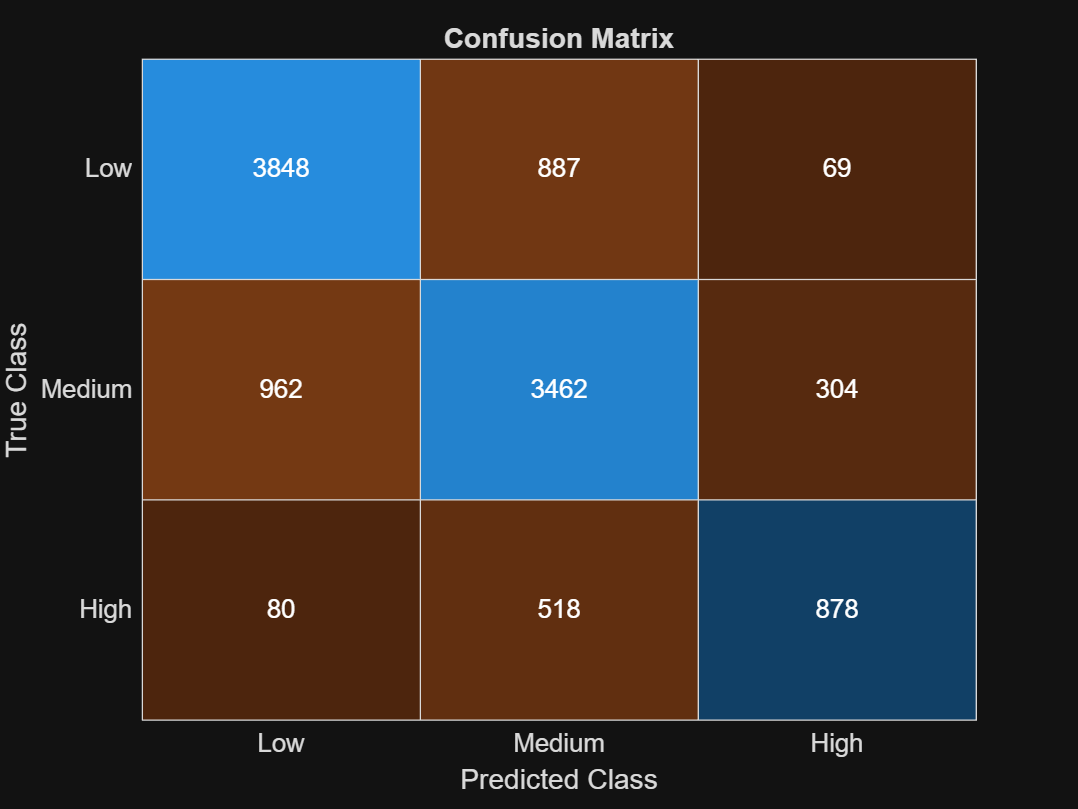

resultsS1_5Tested = struct with fields:
             Accuracy: 0.7438
             PerClass: [3×11 table]
       MacroPrecision: 0.7334
          MacroRecall: 0.7094
     MacroSpecificity: 0.8564
              MacroF1: 0.7198
             MacroFPR: 0.1436
             MacroFDR: 0.2666
    WeightedPrecision: 0.7430
       WeightedRecall: 0.7438
           WeightedF1: 0.7427
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]


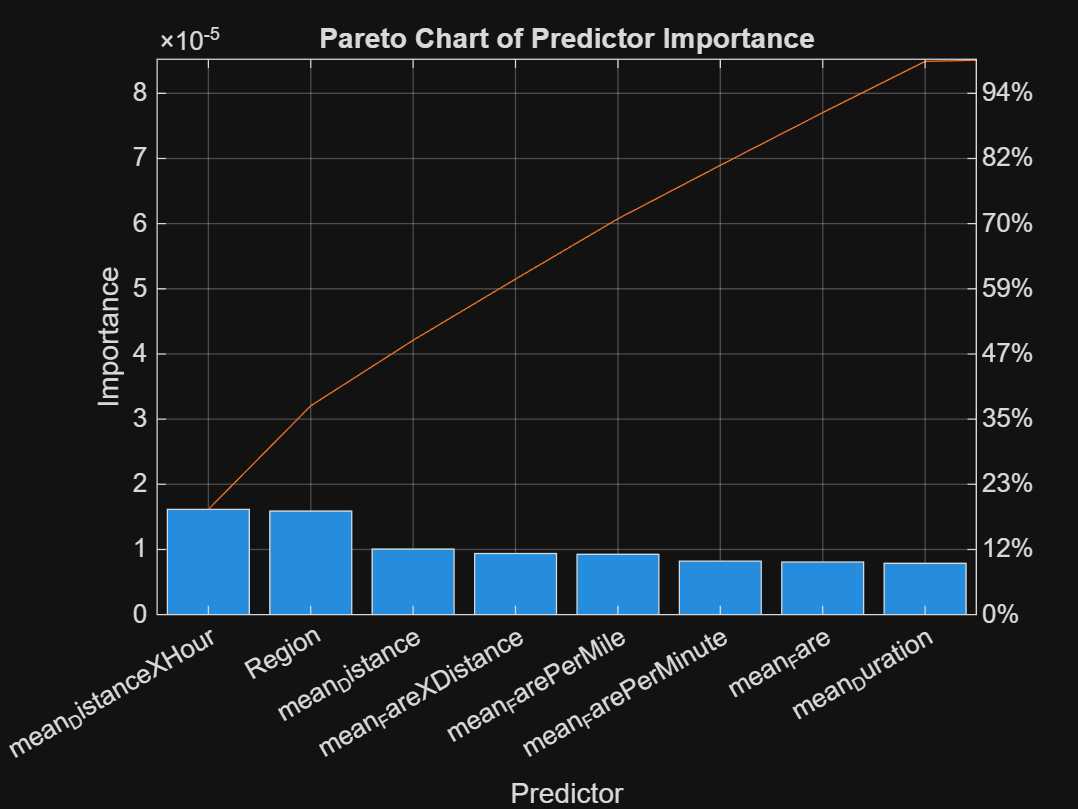

featureEngineering;

featureSelection;

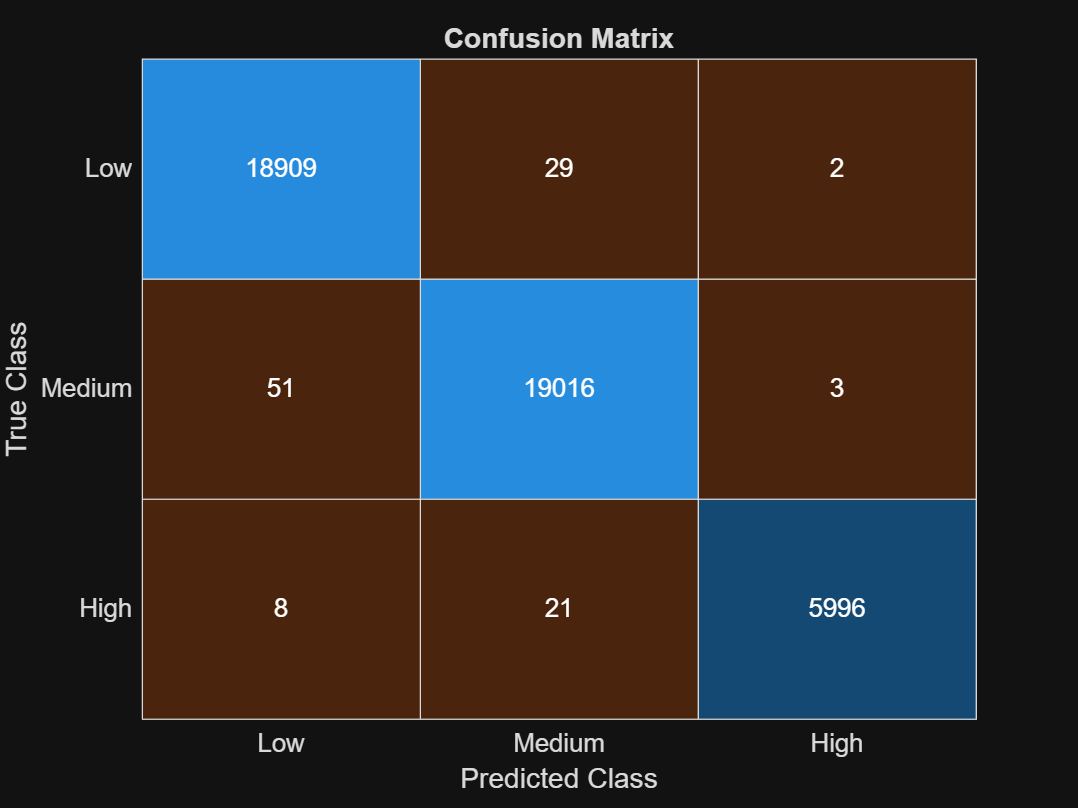

resultsS1 = struct with fields:
             Accuracy: 0.9974
             PerClass: [3×11 table]
       MacroPrecision: 0.9978
          MacroRecall: 0.9969
     MacroSpecificity: 0.9985
              MacroF1: 0.9974
             MacroFPR: 0.0015
             MacroFDR: 0.0022
    WeightedPrecision: 0.9974
       WeightedRecall: 0.9974
           WeightedF1: 0.9974
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]


% Machine Learning part

% Baseline model (Scenario 1)

Mdl = trainBaselineClassifier(trainData);

resultsS1 = evaluateModel(Mdl, trainData, "Demand")

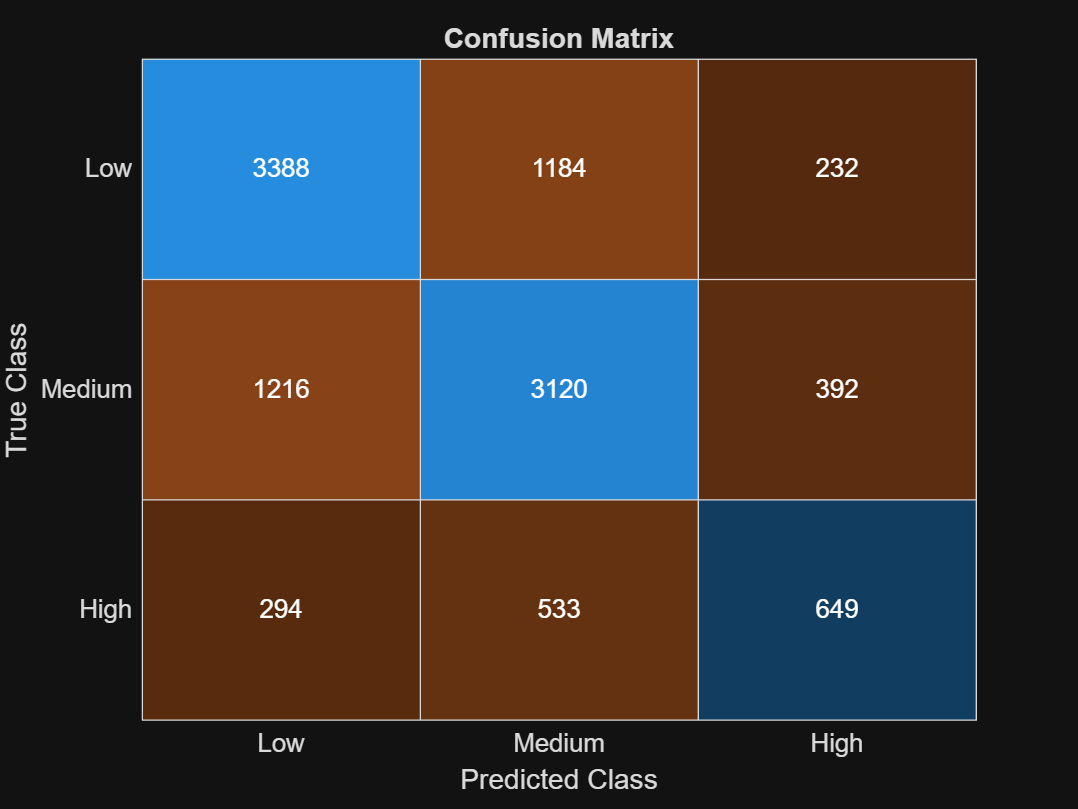

resultsS1Tested = struct with fields:
             Accuracy: 0.6502
             PerClass: [3×11 table]
       MacroPrecision: 0.6155
          MacroRecall: 0.6016
     MacroSpecificity: 0.8059
              MacroF1: 0.6077
             MacroFPR: 0.1941
             MacroFDR: 0.3845
    WeightedPrecision: 0.6473
       WeightedRecall: 0.6502
           WeightedF1: 0.6483
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]



resultsS1Tested = evaluateModel(Mdl, testData, "Demand")

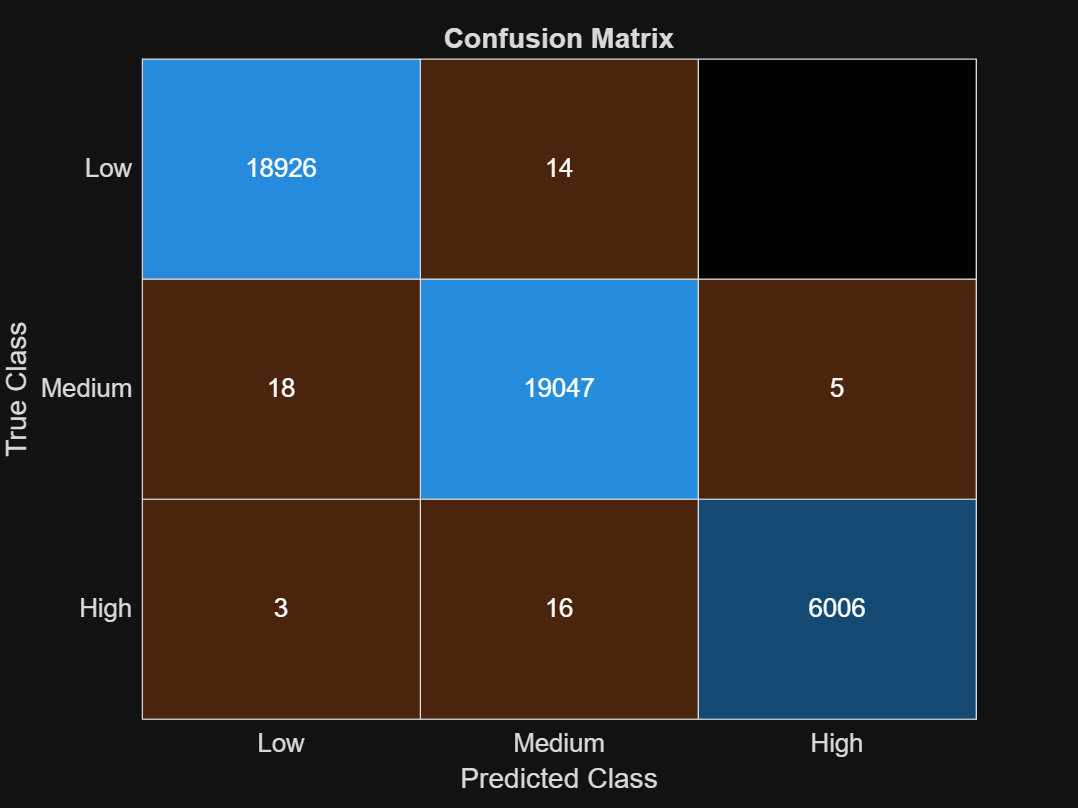

resultsS1_5 = struct with fields:
             Accuracy: 0.9987
             PerClass: [3×11 table]
       MacroPrecision: 0.9988
          MacroRecall: 0.9983
     MacroSpecificity: 0.9993
              MacroF1: 0.9986
             MacroFPR: 7.2335e-04
             MacroFDR: 0.0012
    WeightedPrecision: 0.9987
       WeightedRecall: 0.9987
           WeightedF1: 0.9987
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]



% Best Baseline model (Scenario 1.5)

Mdl1_5 = trainPostFeatureEngineeringBaselineClassifier(trainData);

resultsS1_5 = evaluateModel(Mdl1_5, trainData, "Demand")

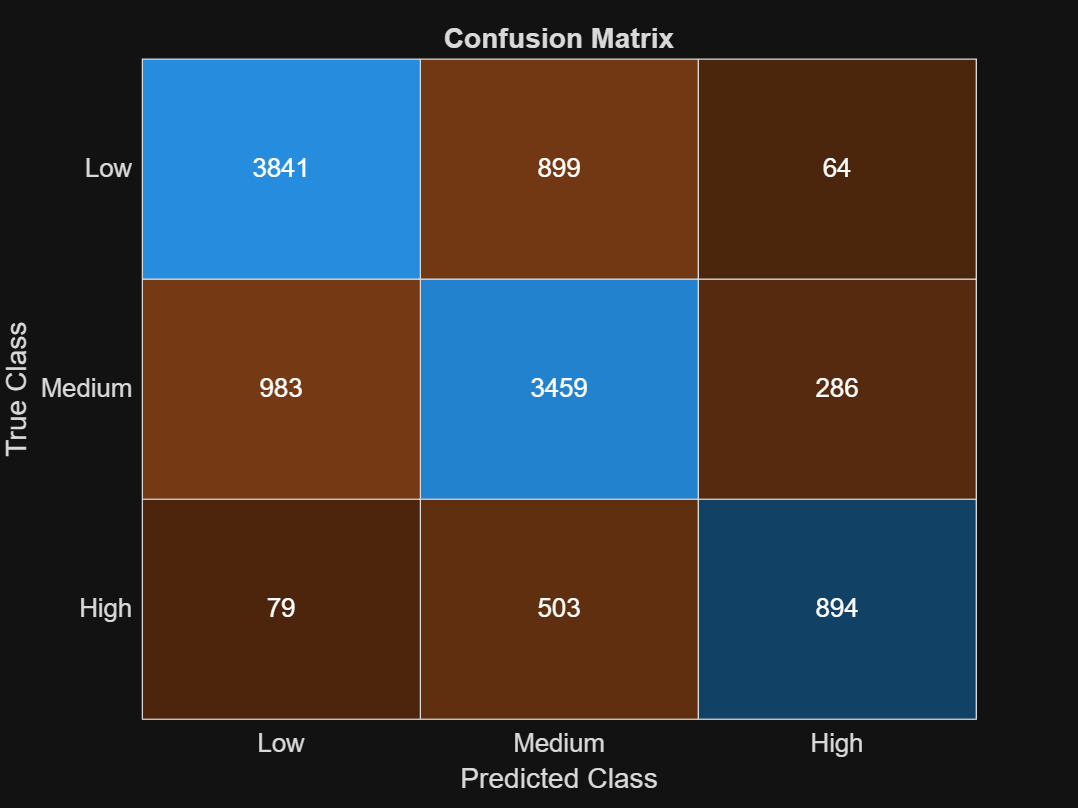

resultsS1_5Tested = struct with fields:
             Accuracy: 0.7444
             PerClass: [3×11 table]
       MacroPrecision: 0.7379
          MacroRecall: 0.7123
     MacroSpecificity: 0.8563
              MacroF1: 0.7234
             MacroFPR: 0.1437
             MacroFDR: 0.2621
    WeightedPrecision: 0.7439
       WeightedRecall: 0.7444
           WeightedF1: 0.7434
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]



resultsS1_5Tested = evaluateModel(Mdl1_5, testData, "Demand")

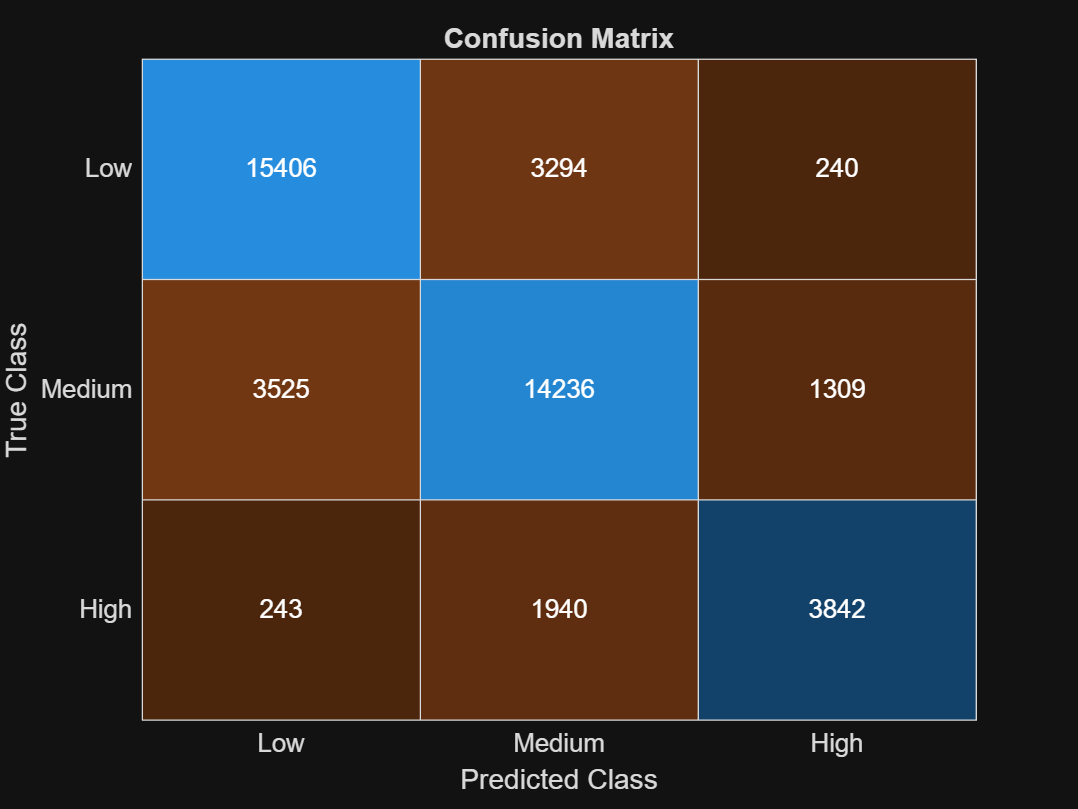

resultsS2 = struct with fields:
             Accuracy: 0.7604
             PerClass: [3×11 table]
       MacroPrecision: 0.7491
          MacroRecall: 0.7325
     MacroSpecificity: 0.8665
              MacroF1: 0.7401
             MacroFPR: 0.1335
             MacroFDR: 0.2509
    WeightedPrecision: 0.7597
       WeightedRecall: 0.7604
           WeightedF1: 0.7597
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]



% Best model (Scenario 2)

Mdl_2 = trainWideNeuralNetworkClassifier(trainData);

resultsS2 = evaluateModel(Mdl_2, trainData, "Demand")

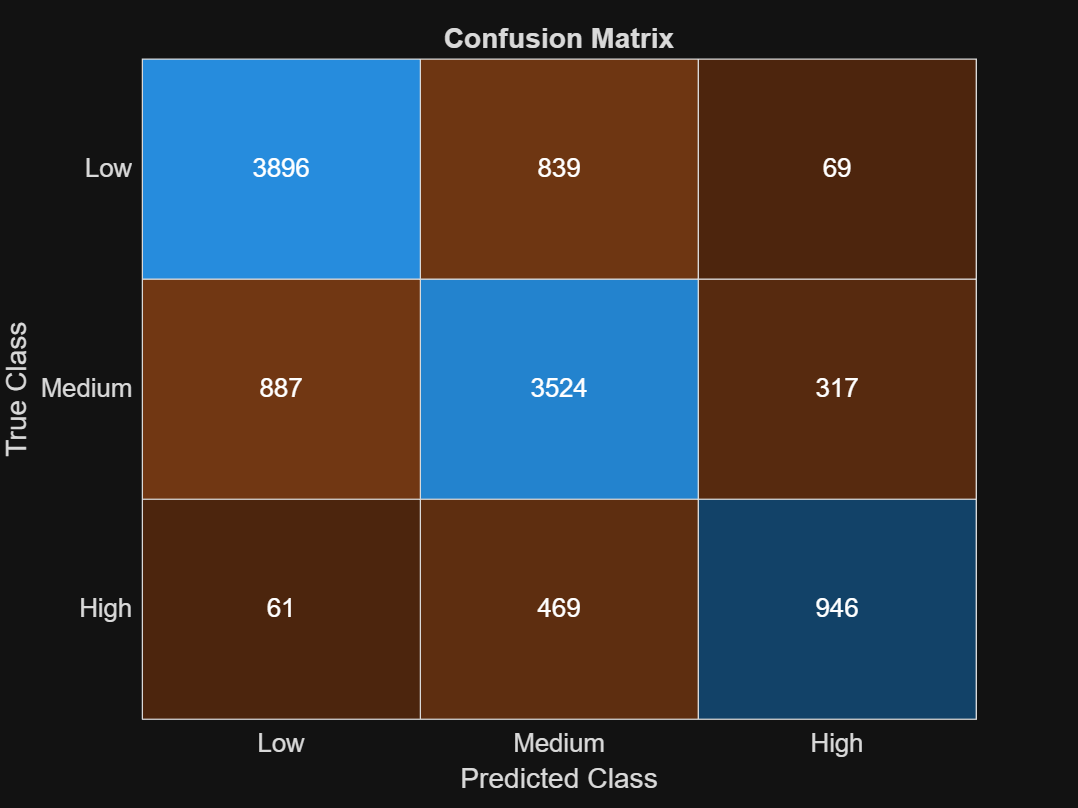

resultsS2Tested = struct with fields:
             Accuracy: 0.7600
             PerClass: [3×11 table]
       MacroPrecision: 0.7479
          MacroRecall: 0.7324
     MacroSpecificity: 0.8661
              MacroF1: 0.7396
             MacroFPR: 0.1339
             MacroFDR: 0.2521
    WeightedPrecision: 0.7595
       WeightedRecall: 0.7600
           WeightedF1: 0.7594
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]



resultsS2Tested = evaluateModel(Mdl_2, testData, "Demand")